# V768 - Measuring Vision with Psychophysics

## Lab 10 - 3D Motion Direction Estimation

In this lab, we return to motion direction estimation, but now in the xz plane. Rather than estimating the direction of a dot field moving across a flat screen, you will view a 3D dot cloud moving through depth: toward you, away from you, and to the left or right. You will report the direction of motion as seen from above using a line indicator.

After collecting data, we will examine how accurately you estimated different directions. Some directions, those that are purely lateral, are relatively straightforward to estimate. Others, those that involve motion that include motion in depth, require the visual system to recover depth motion from subtle differences between the two eyes’ retinal images. We will then compare your 3D estimation performance to 2D data from Lab 7 to see where these limits show up most clearly.

### Learning Outcomes

(i.e., what you will be able to do at the end of this lab)

- Visualize and interpret 3D motion direction estimation data, identifying which directions (lateral vs. in-depth) are estimated more or less accurately.

- Explain why estimating motion direction in 3D is inherently more ambiguous than in 2D, based on the geometry of how 3D motion projects onto the retina.

### Questions

- Include and write a caption for the error-by-direction figure in Part A, Step 3. Your caption should describe the pattern of errors across the full 360° of directions.

- Explain which directions you expect to be hardest to estimate and whether your data line up with that expectation.

- Include and write a caption for the final figure in Part B. 

## Part A. 3D Motion Direction Estimation

### Step 1. Data collection

To collect data, open the Python file` 3d-motion-direction-estimation-xy-indicator.py` in the folder titled `3d-motion-direction-estimation`, and run that experiment. Put on your red-cyan anaglyph glasses (red filter over the left eye, cyan filter over the right eye). The instructions will appear on the screen before the trials begin. A single run of the experiment includes **144 trials**.  Try to complete two runs.

### Step 2. Load your data

#### Find files for specific participant ID

Before running this section of code, enter the participant ID you used below.

participant_id = "demo";

% check current working directory
data_dir = fullfile("3d-motion-direction-estimation", "data");
if ~exist(data_dir, 'dir')
    error("PsychoPy data folder not found. Try changing your " + ...
        "current MATLAB folder to the folder containing this file.")
end

% find csv files
search_pattern = participant_id + "*.csv";
file_info = dir(fullfile(data_dir, search_pattern));

% change variable classes to make them nicer to work with
file_info = struct2table(file_info);
file_info.name = string(file_info.name);
file_info.folder = string(file_info.folder);

% find files for given participant
file_mask = startsWith(file_info.name, participant_id);
file_info = file_info(file_mask,:);

% make sure files were found
n_files = height(file_info);
if n_files == 0
    error("No files found.")
else
    disp("data files found:"); disp(file_info.name)
end

data files found:
demo_3d-motion-direction-estimation_2026-04-08_20h53.15.214.csv


**null** There should be one file.

#### Load and merge data tables

% build full paths
file_info.path = arrayfun(@(d,f) fullfile(d,f), ...
    file_info.folder, file_info.name);

% load data and stack into one table
warning off;
estim3d_data = table;
for ff = 1:n_files
    this_data = readtable(file_info.path(ff));
    estim3d_data = [estim3d_data; this_data];
end
warning on; clear this_data

% display data table size
n_trials = size(estim3d_data, 1);
fprintf("number of trials = %i\n", n_trials)

number of trials = 144


### Step 3. Analyze the data

In this experiment, the stimulus was a cloud of 3D dots rendered as a red-cyan anaglyph. The dots moved in a direction within the **null** (the xz plane — left/right and toward/away from you). The stimulus appeared either to the left or right of fixation. You reported your estimate of the motion direction using the response indicator.

For each trial, the experiment saved the `stim_direction_3d` (the true motion direction, where 0° = rightward, 90° = away, 180° = leftward, 270° = toward), your `response_direction_3d`, the signed `error_3d`, and which `side` the stimulus appeared on.

% extract variables for analysis
stim_direction_3d     = estim3d_data.direction_presented_deg;
response_direction_3d = estim3d_data.response_direction_deg;
error_3d              = estim3d_data.direction_error_deg;
side                  = string(estim3d_data.side);

#### Visualize the response per trial

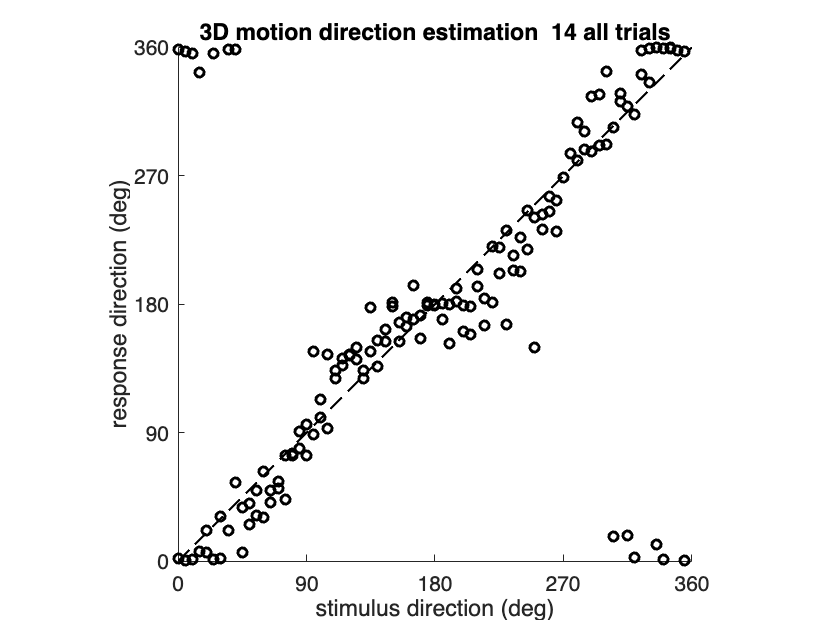

figure; clf; hold on;
scatter(stim_direction_3d, response_direction_3d, 'k', 'LineWidth', 2)
plot([0 360], [0 360], 'k--', 'LineWidth', 1.5)
xlabel('stimulus direction (deg)'); ylabel('response direction (deg)')
title('3D motion direction estimation  14 all trials')
set(gca, 'FontSize', 14, 'XTick', 0:90:360, 'YTick', 0:90:360, ...
    'XLim', [0 360], 'YLim', [0 360])
axis square; drawnow

#### Determine average response per direction

% add circularMean helper to path (defined in this folder)
addpath(fileparts(mfilename('fullpath')))

results_3d = array2table([stim_direction_3d, response_direction_3d], ...
    "VariableNames", ["direction", "response"]);
results_3d = grpstats(results_3d, "direction", "circularMean");
results_3d = renamevars(results_3d, ...
    ["GroupCount", "circularMean_response"], ["n_trials", "mean_response"]);
results_3d.Properties.RowNames = {};
disp(results_3d)

    direction    n_trials    mean_response
    _________    ________    _____________

         0          2           0.19305   
         5          2            358.51   
        10          2            358.34   
        15          2            354.56   
        20          2            13.895   
        25          2            358.38   
        30          2             16.38   
        35          2            10.034   
        40          2            26.602   
        45          2            21.843   
        50          2            33.064   
        55          2            40.602   
        60          2            46.603   
        65          2            45.138   
        70          2            53.563   
        75          2            58.349   
        80          2            74.518   
        85          2            84.726   
        90          2            84.7

#### Plot average response as a function of stimulus direction

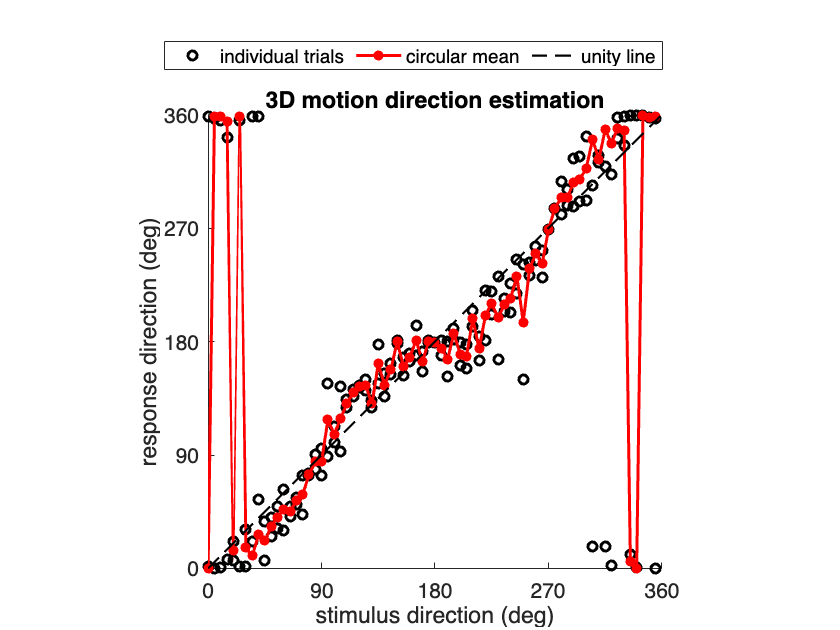

figure; hold on;
scatter(stim_direction_3d, response_direction_3d, 'k', 'LineWidth', 2)
plot(results_3d.direction, results_3d.mean_response, 'r.-', 'MarkerSize', 20, 'LineWidth', 2)
plot([0 360], [0 360], 'k--', 'LineWidth', 1.5)
xlabel('stimulus direction (deg)'); ylabel('response direction (deg)')
title('3D motion direction estimation')
legend({'individual trials', 'circular mean', 'unity line'}, ...
    'Location', 'northoutside', 'NumColumns', 3)
set(gca, 'FontSize', 14, 'XTick', 0:90:360, 'YTick', 0:90:360, ...
    'XLim', [0 360], 'YLim', [0 360])
axis square; drawnow

#### Error as a function of stimulus direction

The scatter plot above shows the overall pattern of responses, but to see where errors are largest we can compute the **null** at each stimulus direction and plot it around a circle. Lateral directions (near 0° and 180°) involve motion that is entirely within the frontoparallel plane and produces a large, symmetric signal on both retinas. In-depth directions (near 90° and 270°) require recovering motion-in-depth from the small difference in how fast each eye's image moves — a much weaker and noisier cue.

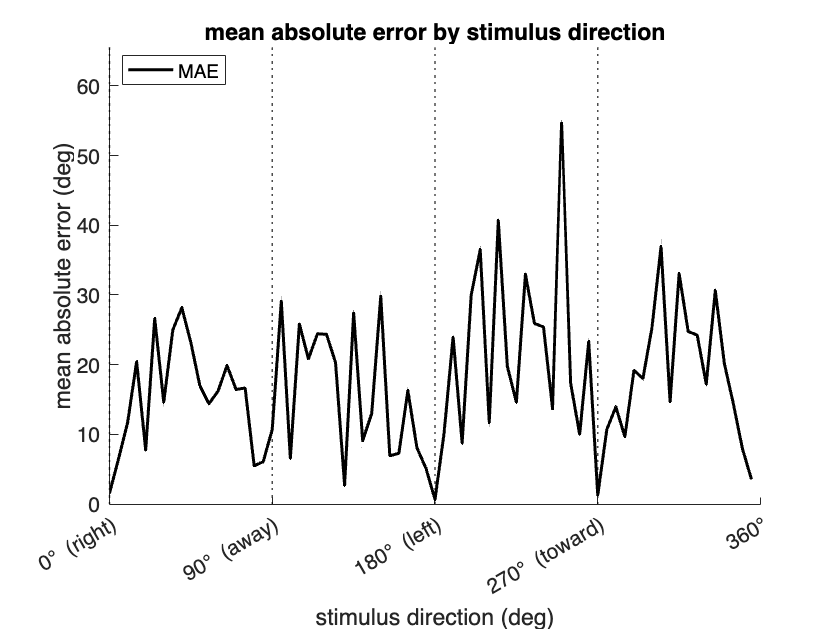

% compute mean absolute error at each stimulus direction
mae_results = array2table([stim_direction_3d, abs(error_3d)], ...
    "VariableNames", ["direction", "abs_error"]);
mae_results = grpstats(mae_results, "direction", "mean");
mae_results = renamevars(mae_results, ...
    ["GroupCount", "mean_abs_error"], ["n_trials", "mae"]);
mae_results.Properties.RowNames = {};

figure; clf; hold on;

% plot MAE
plot(mae_results.direction, mae_results.mae, 'k-', 'LineWidth', 2)

% mark cardinal directions
for d = [0, 90, 180, 270]
    xline(d, 'k:', 'LineWidth', 1)
end
set(gca, 'XTick', [0 90 180 270 360], ...
    'XTickLabel', {'0\circ (right)', '90\circ (away)', '180\circ (left)', '270\circ (toward)', '360\circ'})
xlabel('stimulus direction (deg)'); ylabel('mean absolute error (deg)')
title('mean absolute error by stimulus direction')
legend({'MAE'}, 'Location', 'best')
set(gca, 'FontSize', 14, 'XLim', [0 360], 'YLim', [0 max(mae_results.mae)*1.2])

drawnow

Are errors larger for lateral directions (right/left) or in-depth directions (away/toward)?

## Part B. Comparison to 2D Motion Direction Estimation

In Lab 7, you estimated the direction of 2D motion — dots moving across a flat screen — using the same pointer-based response method. The key difference is that in the 2D task every direction was a frontoparallel motion, so there was no motion-in-depth component. Here we load those data and compare estimation accuracy across the full 360° to see where the 3D task is harder, and where (if anywhere) it is not.

### Step 1. Load the 2D estimation data

#### Find files for specific participant ID

Enter the same participant ID you used in Lab 7 below.

participant_id_2d = "demo";

data_dir_2d = fullfile("..", "07-motion-direction", "2d-motion-direction-estimation", "data");
if ~exist(data_dir_2d, 'dir')
    error("2D estimation data folder not found. " + ...
        "Make sure Lab 7 data is available at ../07-motion-direction/")
end

search_pattern_2d = participant_id_2d + "*.csv";
file_info_2d = dir(fullfile(data_dir_2d, search_pattern_2d));

file_info_2d = struct2table(file_info_2d);
file_info_2d.name = string(file_info_2d.name);
file_info_2d.folder = string(file_info_2d.folder);

file_mask_2d = startsWith(file_info_2d.name, participant_id_2d);
file_info_2d = file_info_2d(file_mask_2d,:);

n_files_2d = height(file_info_2d);
if n_files_2d == 0
    error("No 2D estimation files found.")
else
    disp("2D data files found:"); disp(file_info_2d.name)
end

2D data files found:
demo_2d-motion-direction-estimation_2025-02-26_22h06.12.747.csv


There should be one file.

#### Load and merge data tables

file_info_2d.path = arrayfun(@(d,f) fullfile(d,f), ...
    file_info_2d.folder, file_info_2d.name);

warning off;
estim2d_data = table;
for ff = 1:n_files_2d
    this_data = readtable(file_info_2d.path(ff));
    this_data(1,:) = [];  % remove PsychoPy Builder instruction row
    estim2d_data = [estim2d_data; this_data];
end
warning on; clear this_data

n_trials_2d = size(estim2d_data, 1);
fprintf("number of 2D trials = %i\n", n_trials_2d)

number of 2D trials = 112


### Step 2. Compute 2D errors

For the 2D estimation data, the stimulus direction is stored in `stim_direction_2d` and the response in `response_direction_2d`. The pointer orientation is stored as a clockwise rotation from up, so we convert it to a standard counterclockwise-from-right convention with `error_2d`.

stim_direction_2d     = estim2d_data.orientation;
response_direction_2d = mod(360 - estim2d_data.pointer_orientation, 360);
error_2d = mod(response_direction_2d - stim_direction_2d + 180, 360) - 180;

% compute mean absolute error per direction for 2D
mae_results_2d = array2table([stim_direction_2d, abs(error_2d)], ...
    "VariableNames", ["direction", "abs_error"]);
mae_results_2d = grpstats(mae_results_2d, "direction", "mean");
mae_results_2d = renamevars(mae_results_2d, ...
    ["GroupCount", "mean_abs_error"], ["n_trials", "mae"]);
mae_results_2d.Properties.RowNames = {};

### Step 3. Compare the data

#### Side-by-side polar error plots

Below we plot mean absolute error as a function of stimulus direction for both experiments on the same scale. The shaded regions mark the in-depth directions (away and toward). 

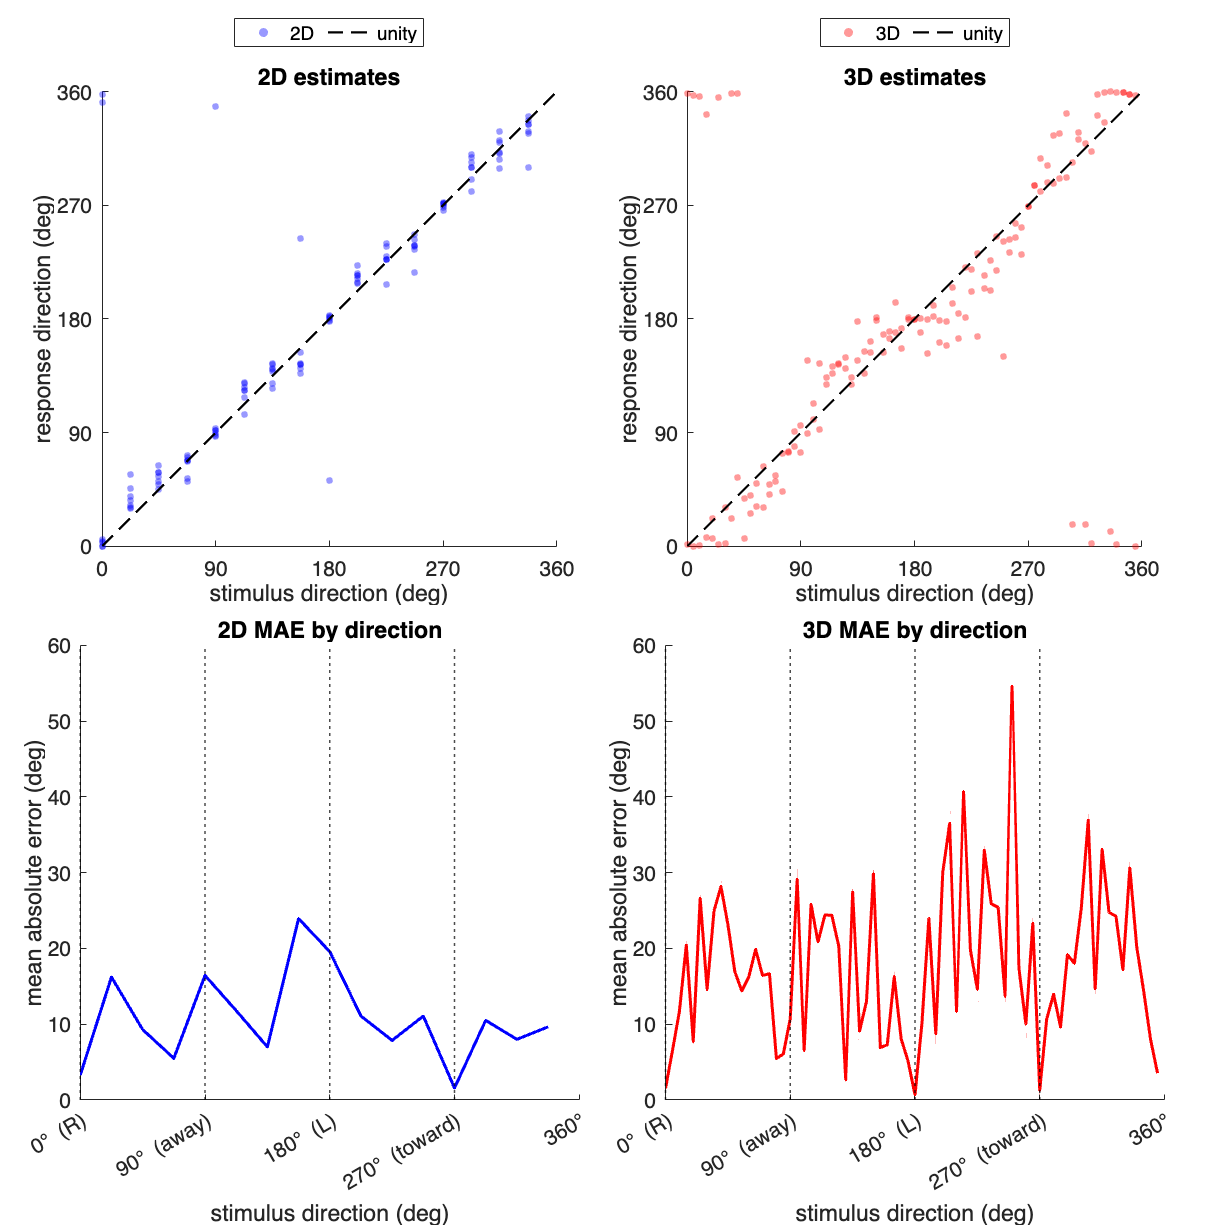


figure;
tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
set(gcf, 'Position', [0 0 1000 1000])

% --- panel 1-2: side-by-side scatter plots ---
nexttile; hold on;
scatter(stim_direction_2d, response_direction_2d, 20, 'b', 'filled', 'MarkerFaceAlpha', 0.4)
plot([0 360], [0 360], 'k--', 'LineWidth', 1.5)
xlabel('stimulus direction (deg)'); ylabel('response direction (deg)')
title('2D estimates')
legend({'2D','unity'}, 'Location', 'northoutside', 'NumColumns', 3)
set(gca, 'FontSize', 14, 'XTick', 0:90:360, 'YTick', 0:90:360, ...
    'XLim', [0 360], 'YLim', [0 360])
axis square;

nexttile; hold on;
scatter(stim_direction_3d, response_direction_3d, 20, 'r', 'filled', 'MarkerFaceAlpha', 0.4)
plot([0 360], [0 360], 'k--', 'LineWidth', 1.5)
xlabel('stimulus direction (deg)'); ylabel('response direction (deg)')
title('3D estimates')
legend({'3D', 'unity'}, 'Location', 'northoutside', 'NumColumns', 3)
set(gca, 'FontSize', 14, 'XTick', 0:90:360, 'YTick', 0:90:360, ...
    'XLim', [0 360], 'YLim', [0 360])
axis square


nexttile; hold on;
for d = [0, 90, 180, 270]
    xline(d, 'k:', 'LineWidth', 1)
end

plot(mae_results_2d.direction, mae_results_2d.mae, 'b-', 'LineWidth', 2)
xlabel('stimulus direction (deg)'); ylabel('mean absolute error (deg)')
title('2D MAE by direction')
set(gca, 'FontSize', 14, 'XTick', [0 90 180 270 360], ...
    'XTickLabel', {'0\circ (R)', '90\circ (away)', '180\circ (L)', '270\circ (toward)', '360\circ'}, ...
    'XLim', [0 360], 'YLim', [0 60])

nexttile; hold on;
for d = [0, 90, 180, 270]
    xline(d, 'k:', 'LineWidth', 1)
end

plot(mae_results.direction, mae_results.mae, 'r-', 'LineWidth', 2)
xlabel('stimulus direction (deg)'); ylabel('mean absolute error (deg)')
title('3D MAE by direction')
set(gca, 'FontSize', 14, 'XTick', [0 90 180 270 360], ...
    'XTickLabel', {'0\circ (R)', '90\circ (away)', '180\circ (L)', '270\circ (toward)', '360\circ'}, ...
    'XLim', [0 360], 'YLim', [0 60])

drawnow

fprintf("average 2D MAE:%.2f", mean(mae_results_2d.mae))

average 2D MAE:10.79

fprintf("average 3D MAE:%.2f", mean(mae_results.mae))

average 3D MAE:17.93